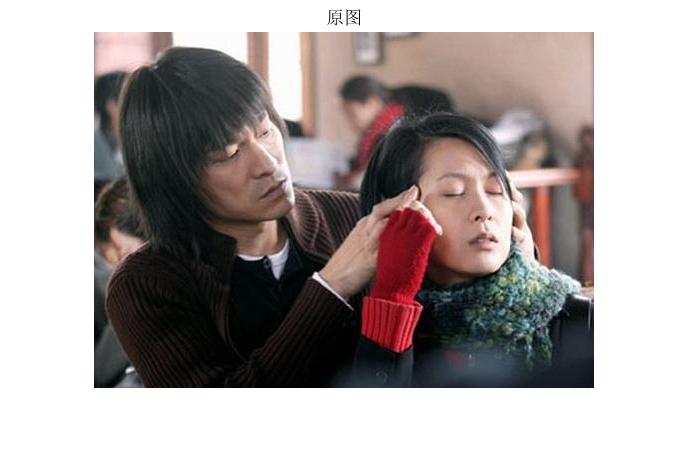

clc;clear;close all;%开局操作
image_original=imread("08-刘德华.jpg");
figure;
imshow(image_original);
title("原图");

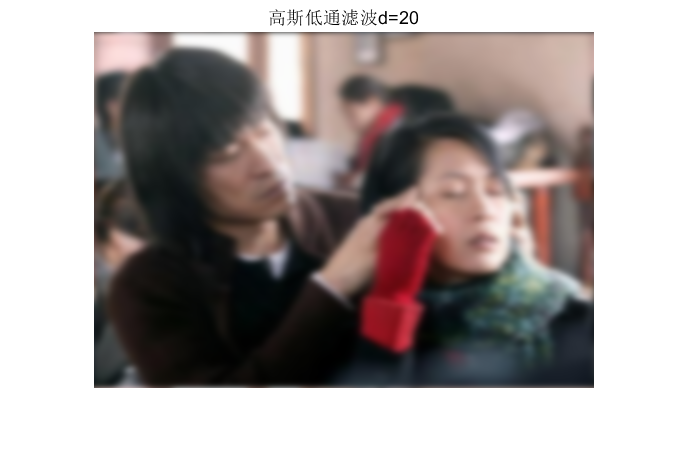

d=20;
image=image_original;%创建副本
image(:,:,1)=gaush(image(:,:,1),d);%分别高斯滤波
image(:,:,2)=gaush(image(:,:,2),d);
image(:,:,3)=gaush(image(:,:,3),d);
figure;imshow(image);title('高斯低通滤波d=20');%展示结果

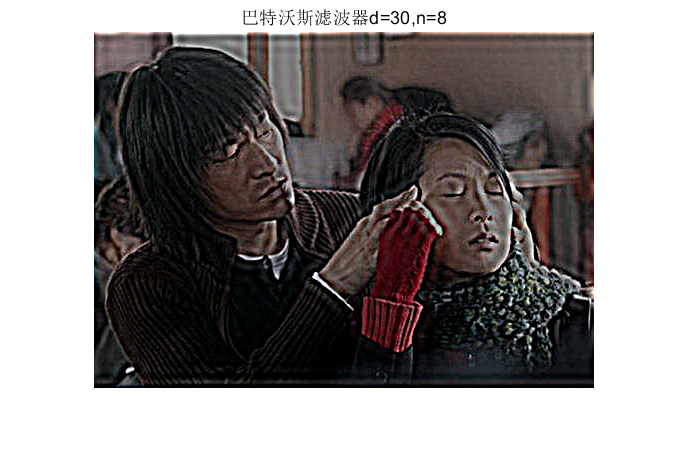

d=30;
n=8;
image=image_original;%创建副本
image(:,:,1)=freqfilter_btw_Hp(image(:,:,1),d,n);%分别高斯滤波
image(:,:,2)=freqfilter_btw_Hp(image(:,:,2),d,n);
image(:,:,3)=freqfilter_btw_Hp(image(:,:,3),d,n);
figure;imshow(image);title('巴特沃斯滤波器d=30,n=8');%展示结果

function im5 = freqfilter_btw_Hp(im,D0,n)%巴特沃斯滤波器
% 巴特沃斯高通滤波器
% input:
%     M,N:频域滤波器的尺寸
%     D0：带阻滤波器的截止频率
%     n ：阶次
% output:
%       H：M x N的矩阵，表示频域滤波器矩阵，数据类型为double，
    if ~isa(im,'double')
        im1 = double(im)/255; 
    end
im2 = fft2(im1);      % 傅里叶变换
im3 = fftshift(im2);  % 中心化
result=zeros(size(im3));
[N1, N2] = size(im3);
n1 = fix(N1 / 2);
n2 = fix(N2 / 2);
for i = 1:N1
    for j = 2:N2
        d = sqrt((i-n1)^2+(j-n2)^2);
        if d==0
            h=0;
        else
            h = 1/(1 + (D0 / d)^(2*n));
            h = 0.5+2*h;  % 巴特沃斯高通滤波器
        end
        result(i,j) = h * im3(i,j);
    end
end
result = ifftshift(result);    % 反中心化
im4 = ifft2(result);           % 反变换
im5 = im2uint8(real(im4));     % 滤波图像
end
%%
%%

function img_lpf=gaush(image,d0)%高斯滤波函数
[M ,N]=size(image);
%d0,阈值
img_f = fft2(double(image));%傅里叶变换得到频谱
img_f=fftshift(img_f);  %移到中间

m_mid=floor(M/2);%中心点坐标
n_mid=floor(N/2);  

h = zeros(M,N);%高斯低通滤波器构造
for i = 1:M
    for j = 1:N
        d = ((i-m_mid)^2+(j-n_mid)^2);
        h(i,j) = exp(-(d)/(2*(d0^2)));      
    end
end

img_lpf = h.*img_f;

img_lpf=ifftshift(img_lpf);    %中心平移回原来状态
img_lpf=uint8(real(ifft2(img_lpf)));  %反傅里叶变换,取实数部分

end



